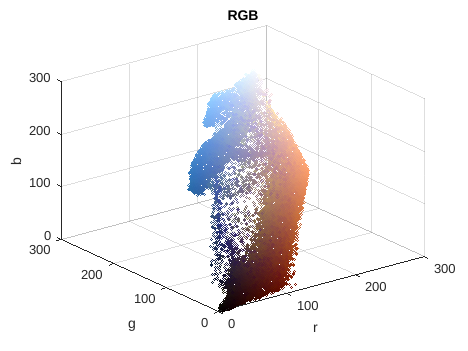

% a)
pic = imread("archesrgbklein.png");
% b)
figure;
list_rgb = reshape(pic,[],3);
color = double(list_rgb)./255;
scatter3(list_rgb(:,1), list_rgb(:,2), list_rgb(:,3), 1, color)
xlabel("r");
ylabel("g");
zlabel("b");
title("RGB");


small_pic = imresize(pic, 0.4, "nearest"); 
small_list_rgb = reshape(small_pic,[],3);
color = double(small_list_rgb)./255;
scatter3(small_list_rgb(:,1), small_list_rgb(:,2), small_list_rgb(:,3), 1, color)
xlabel("r");
ylabel("g");
zlabel("b");
title("RGB");

% c)
small_pic = imresize(pic, 0.2, "nearest"); 
% conversion 2 double because of addition error in kmeans
small_list_rgb = double(reshape(small_pic,[],3));

k = 8;
[idx, centers] = kmeans(small_list_rgb, k, 'distance', 'sqEuclidean', 'Replicates', 3);

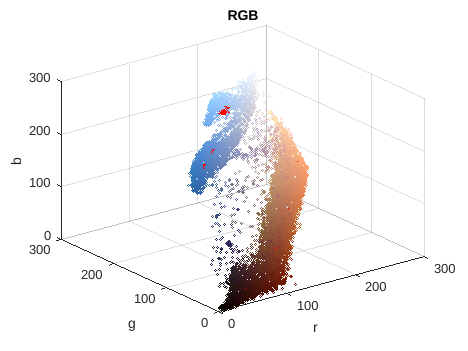

ans =    69.6012  126.9195  191.0467
   69.6012  126.9195  191.0467
   69.6012  126.9195  191.0467
   69.6012  126.9195  191.0467
   69.6012  126.9195  191.0467
   69.6012  126.9195  191.0467
   69.6012  126.9195  191.0467
   69.6012  126.9195  191.0467
   69.6012  126.9195  191.0467
   69.6012  126.9195  191.0467


ans =    120   160     3


hold on;
scatter3(centers(:, 1), centers(:, 2), centers(:, 3), 'r*', 'LineWidth', 5);
hold off;

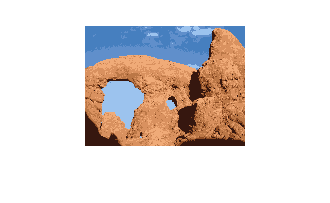


center_pic = reshape(centers(idx,:), size(small_pic));
center_pic = uint8(center_pic);
figure;
imshow(center_pic);


% e)
idx_original = kmeans(double(reshape(pic,[],3)),k,'MaxIter',1,'Start',centers);

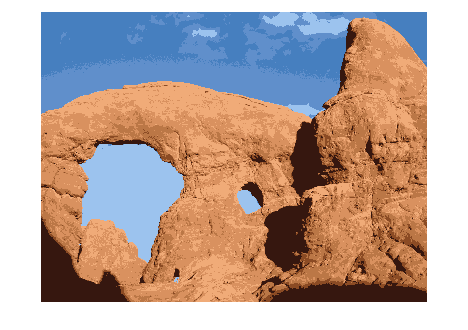

orig_center_pic = uint8(reshape(centers(idx_original,:), size(pic)));
figure;
imshow(orig_center_pic);

% Wir können die Wahrnung ignorieren das wir den prozess mit dem kleinen
% Bild schon durchlaufen sind und 

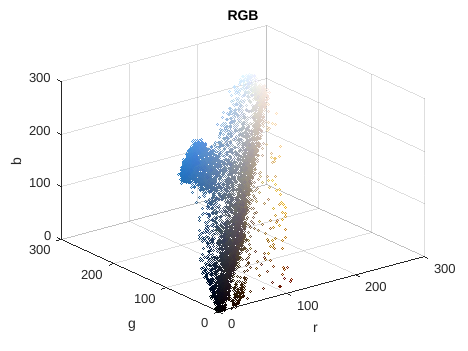

% f)

pic = imread("moewex.jpg");

figure;
list_rgb = reshape(pic,[],3);
color = double(list_rgb)./255;
scatter3(list_rgb(:,1), list_rgb(:,2), list_rgb(:,3), 1, color)
xlabel("r");
ylabel("g");
zlabel("b");
title("RGB");

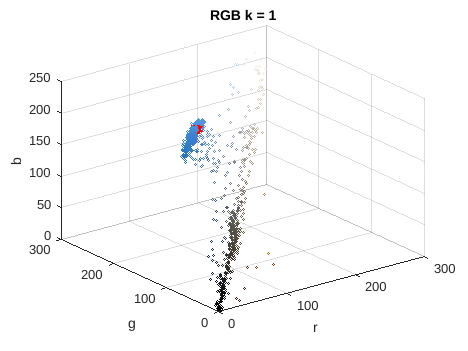

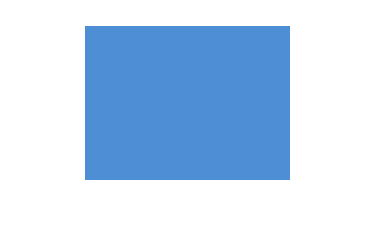

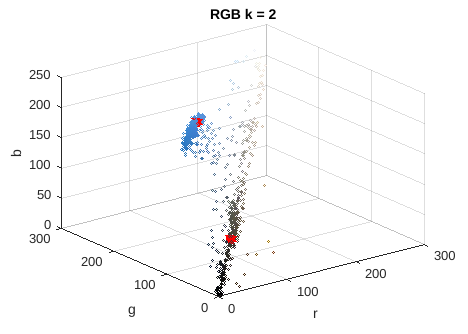

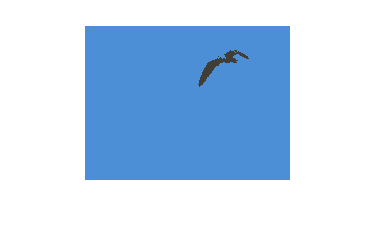

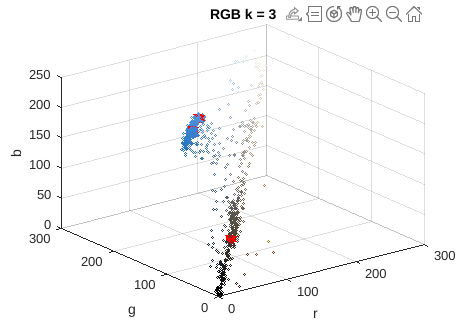

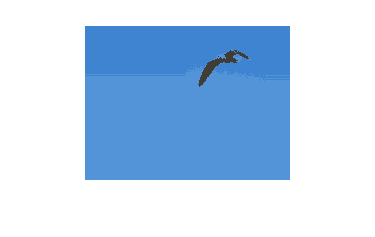

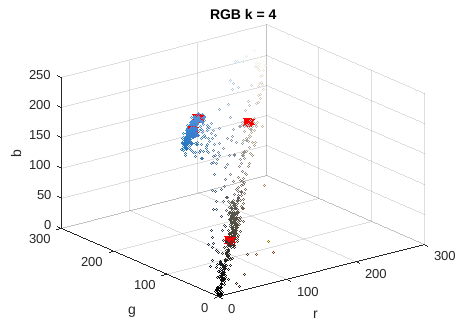

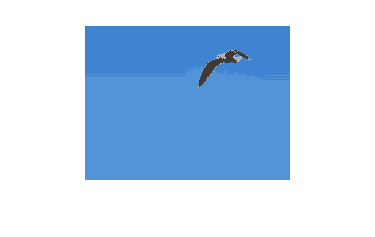


small_pic = imresize(pic, 0.2, "nearest"); 
small_list_rgb = reshape(small_pic,[],3);
color = double(small_list_rgb)./255;

for i = 1:10
    scatter3(small_list_rgb(:,1), small_list_rgb(:,2), small_list_rgb(:,3), 1, color)
    xlabel("r");
    ylabel("g");
    zlabel("b");
    title("RGB k = " + i);
    k = i;
    [idx, centers] = kmeans(double(small_list_rgb), k, 'distance', 'sqEuclidean', 'Replicates', 3);
    hold on;
    scatter3(centers(:, 1), centers(:, 2), centers(:, 3), 'r*', 'LineWidth', 5);
    hold off;
    
    center_pic = reshape(centers(idx,:), size(small_pic));
    center_pic = uint8(center_pic);
    figure;
    imshow(center_pic);
    
    % e)
    idx_original = kmeans(double(reshape(pic,[],3)),k,'MaxIter',1,'Start',centers);
    orig_center_pic = uint8(reshape(centers(idx_original,:), size(pic)));
    figure;
    imshow(orig_center_pic);
end

pic = imread("archesrgbklein.png");

small_pic = imresize(pic, 0.2, "nearest"); 
small_list_rgb = reshape(small_pic,[],3);
color = double(small_list_rgb)./255;
scatter3(small_list_rgb(:,1), small_list_rgb(:,2), small_list_rgb(:,3), 1, color)
xlabel("r");
ylabel("g");
zlabel("b");
title("RGB");

k = 8;
[idx, centers] = kmeans(double(small_list_rgb), k, 'distance', 'sqEuclidean', 'Replicates', 3);

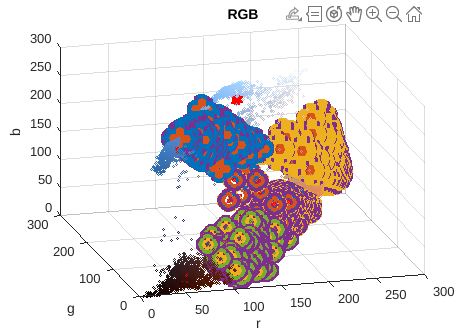

hold on;
for i = 1:7
    scatter3(small_list_rgb(idx==1,1),small_list_rgb(idx==1,2),small_list_rgb(idx==1,3), centers(i),'LineWidth',3)
end
hold off